# Example 6.28: Classification of Flow Cytometry Data (Case I)

Note: this script reproduces Example 6.28 (Section 6.7.2) of **Statistics for Chemical Engineers**: a CNN that classifies scatter fields of liquid-crystal droplets by endotoxin presence. Victor Z UW-Madison, 2020 use CNN for clasifying flow cytometry fields (case I)

clc; clear all; close all hidden;

digitDatasetPath = [pwd,'/Data/Endotoxins_CaseI/Gray'];

imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

n=length(imds.Labels);

## Data

shuffle images to randomize

rng(0);
imds = shuffle(imds);

% select only a subset to accelerate
indices = 1:n;
imds = subset(imds,indices);

% count number of points with each label

labelCount = countEachLabel(imds)

labelCount = 2×2 table
     Label     Count
    _______    _____
    bipolar     49  
    radial      49  
	Get insights using Copilot


% determine size of images
img = readimage(imds,1);
siz=size(img)

siz =     50    50



% creare training and validation sets
numTrainFiles = 15; % number of files in each label
rng(0);
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## CNN

define CNN architecture

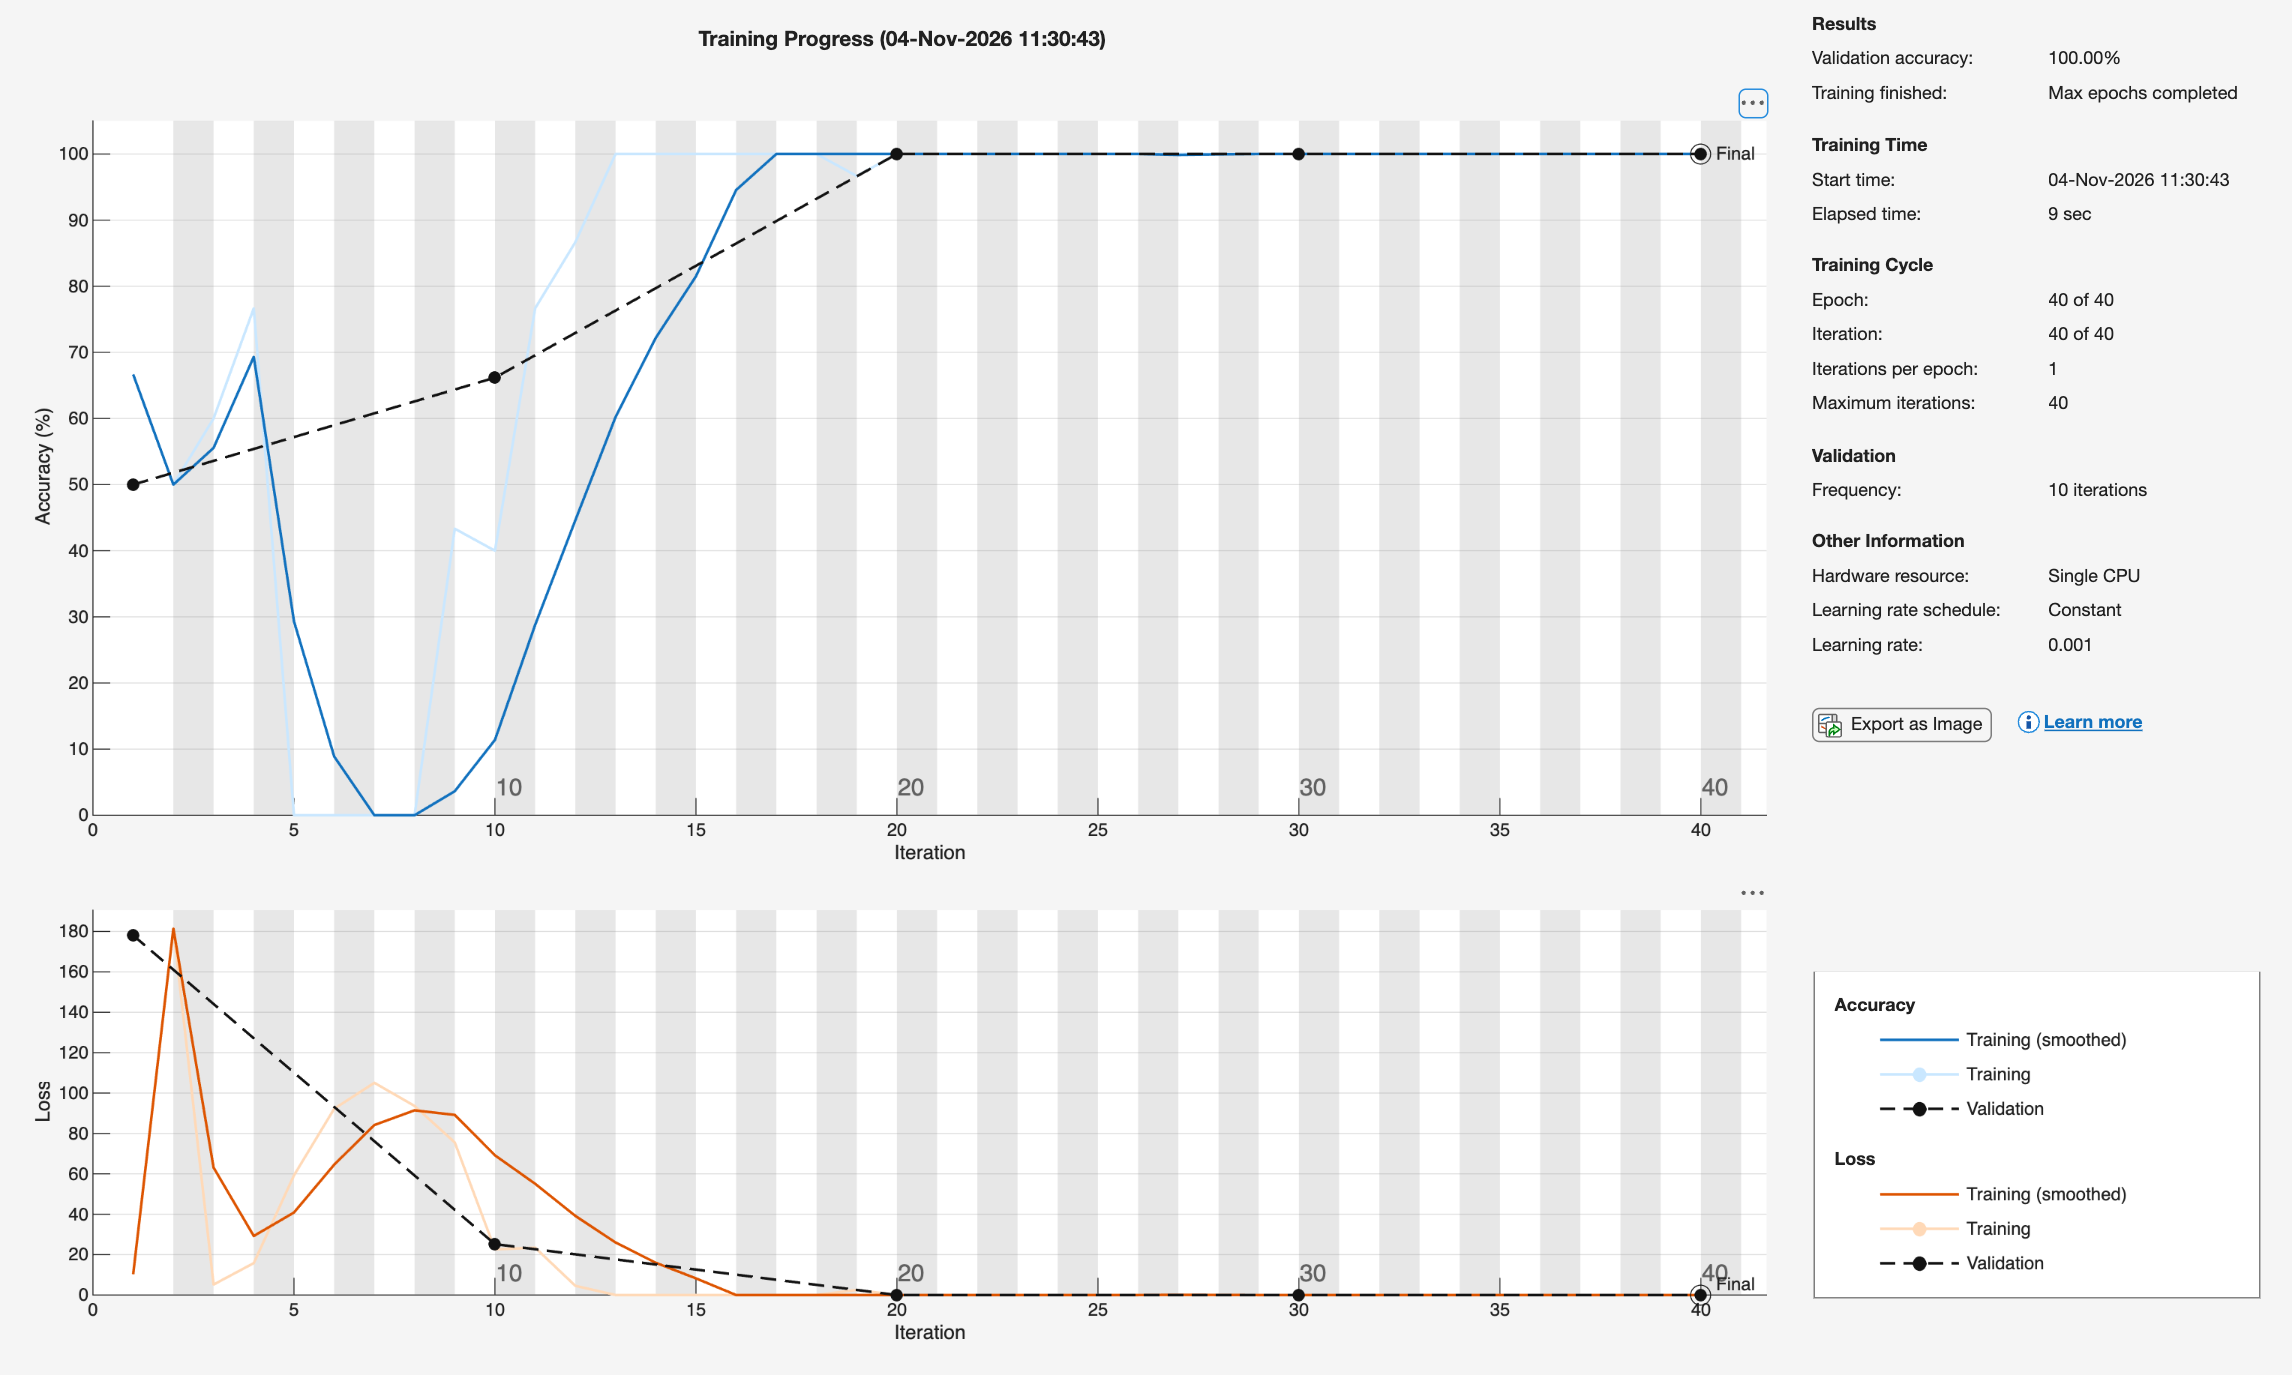

layers = [
    imageInputLayer([50 50 1]) % height, width, and channel size
    
    convolution2dLayer(3,1,'Padding','same')
    reluLayer
    
    fullyConnectedLayer(2) % fully connected layer has 2 classes
    softmaxLayer
    classificationLayer
    ];

% train CNN

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.001, ...
    'MaxEpochs',40, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',10, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(imdsTrain,layers,options);

## save neural network object for re-use

%load endotoxin_net_caseI;
%net=endotoxin_net_caseI;
%save endotoxin_net_caseI;

% display architecture
% analyzeNetwork(net)

## Accuracy and confusion matrices

obtain training accuracy

YPredT = classify(net,imdsTrain);
YTrain = imdsTrain.Labels;
accuracy = sum(YPredT == YTrain)/numel(YTrain)

accuracy = 1


% confusion matrix
figure(2)
subplot(2,2,1)
ConfusionTrain = confusionchart(YTrain,YPredT,'DiagonalColor',[1 1 1],'OffDiagonalColor',[0,0,0]);
xlabel('Predicted')
ylabel('True')

% obtain validation accuracy
YPredV = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPredV == YValidation)/numel(YValidation)

accuracy = 1

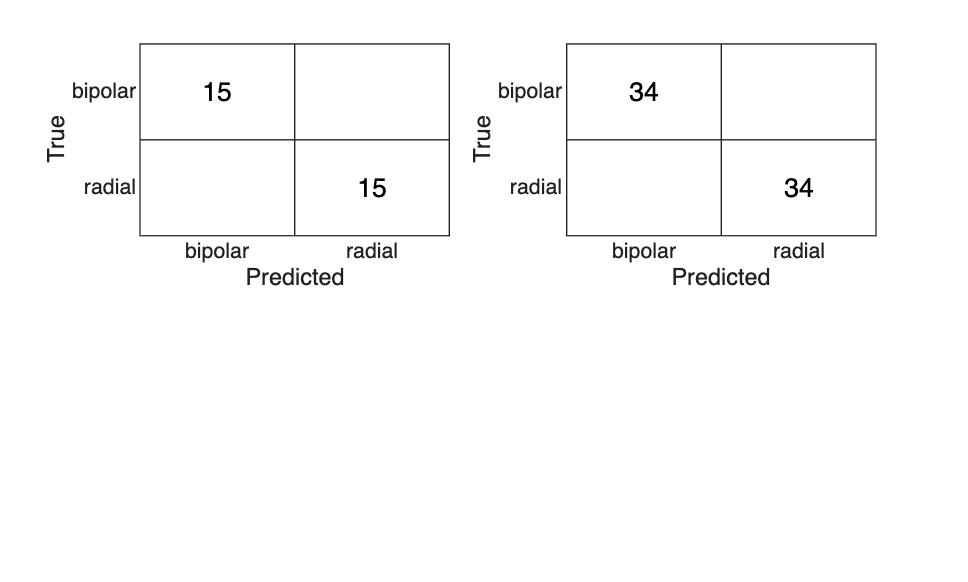


% confusion matrix
figure(2)
subplot(2,2,2)
ConfusionTrain = confusionchart(YValidation,YPredV,'DiagonalColor',[1 1 1],'OffDiagonalColor',[0,0,0]);
xlabel('Predicted')
ylabel('True')

print -depsc ch6_endotoxins_confusion_caseI.eps


% display filters
net.Layers(2).Weights

ans = 3×3 single matrix
   -1.6853   -0.5528   -1.1559
   -1.7911   -1.0683   -0.4127
   -0.9628   -0.2769   -0.1229


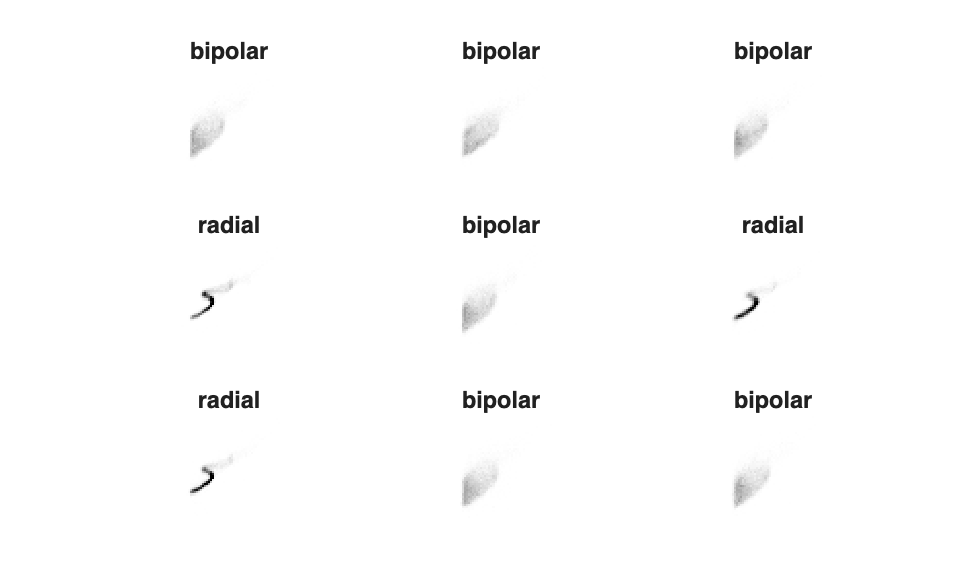


% Display some of the images in the datastore.

figure(1)
for i = 1:9
    subplot(3,3,i);
    imshow(imdsValidation.Files{i});
    title(imdsValidation.Labels(i))
end
print -depsc ch6_endotoxins_data_caseI.eps

## Activations

get activations

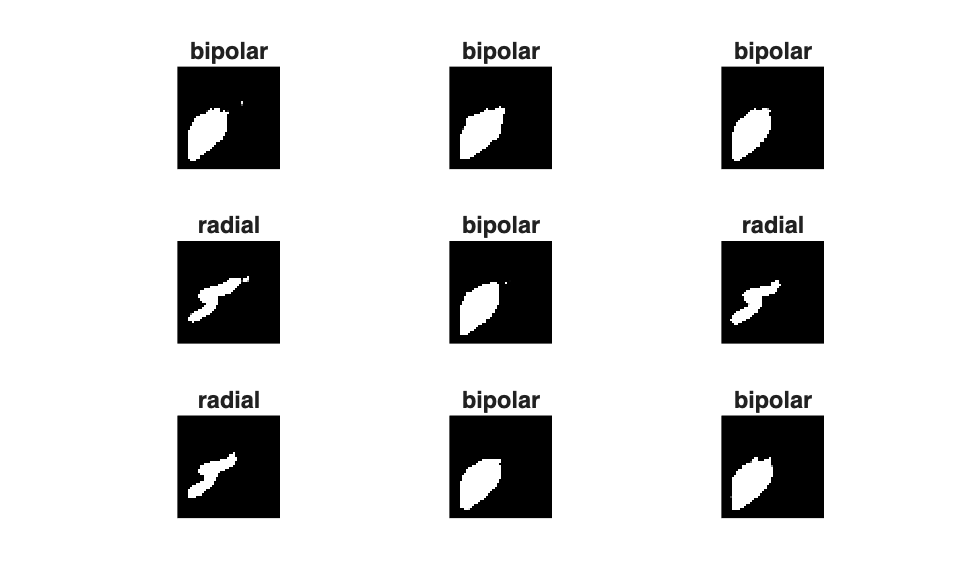

Act = activations(net,imdsValidation,2);

figure(3)
for i=1:9
    subplot(3,3,i)
    imshow(Act(:,:,1,i))
    title(imdsValidation.Labels(i))
end
print -depsc ch6_endotoxins_activations_caseI.eps

## Note

As in the book, the CNN filter highlights the shape of the scatter field: fields with a bipolar shape (no endotoxin) occupy a larger volume.